## Q1 (C)

s = tf('s');

Plant transfer funciton

G = (100*(0.5*s+1))/(s*(0.2*s+1)*(s+10))

G =
 
        50 s + 100
  ----------------------
  0.2 s^3 + 3 s^2 + 10 s
 
Continuous-time transfer function.



Compute the margins of the transfer funciton.

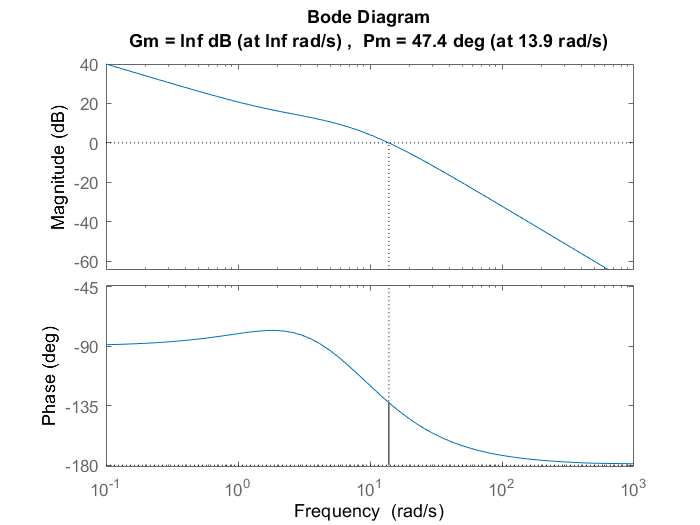

margin(G)

Step response of the closed-loop system

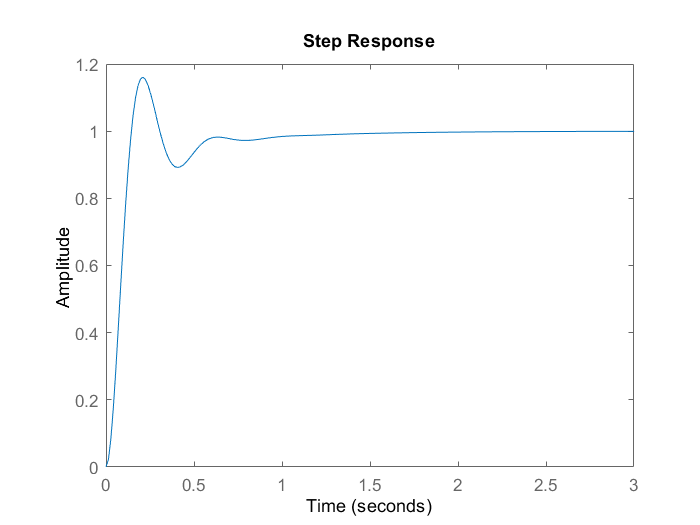

step(G/(1+G))

[Gm,Pm,Wcg,Wcp] = margin(G)

Gm = Inf

Pm = 47.3637

Wcg = Inf

Wcp = 13.8869

The margins obtained using MATLAB are close to the ones obtained using the bode plots drawn by hand.

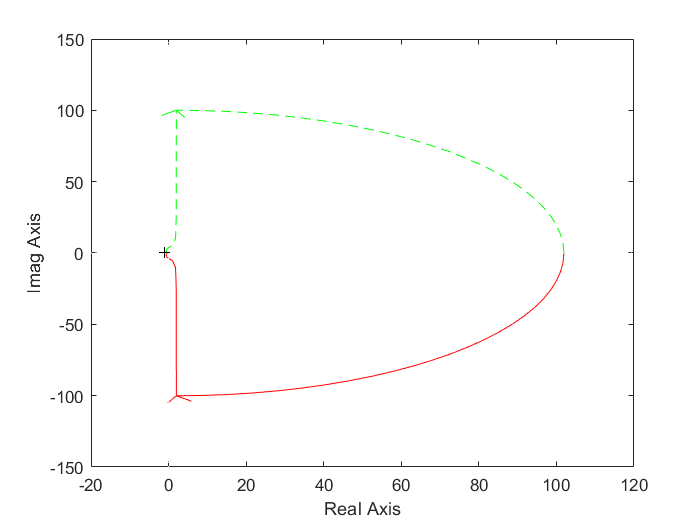

nyquist1(G)